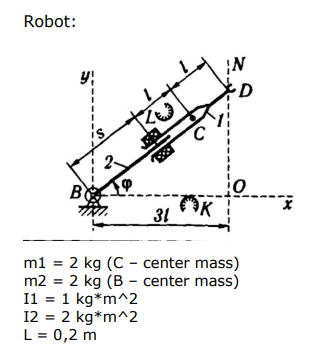

To make things consistent Joint 1 will be the revolute and Joint 2 will be the prismatic

m1 = m2 = 2 kg 

I1 = 2 kg*m^2

I2 = 1 kg*m^2

L = 0.2 m

clear variables
syms q1 q2 dq1 dq2 ddq1 ddq2 L m1 m2 I1 I2 g real

## Forward kinematics for each joint and center

T00 = eye(4);
T01 = Rz(q1);
T01c = Rz(q1)

$$T01c = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02= Rz(q1) * Tx(q2)* Tx(2*L);
T02c = Rz(q1) * Tx(q2)* Tx(L)

$$T02c = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & L\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & L\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Joint centers and Joint origins

O0 = T00(1:3,4)

O0 =      0
     0
     0


O1 = T01(1:3,4)

$$O1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Oc1 = T01c(1:3,4)

$$Oc1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

O2 = T02(1:3,4)

$$O2 = \left(\begin{array}{c} 2\,L\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ 2\,L\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

Oc2 = T02c(1:3,4)

$$Oc2 = \left(\begin{array}{c} L\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ L\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

## Get the Z vectors for each joint

Z0 = T01(1:3,3) %Rz

$$Z0 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Z1 = T02(1:3,1) %Tx

$$Z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

## Get the Linear velocity for each joint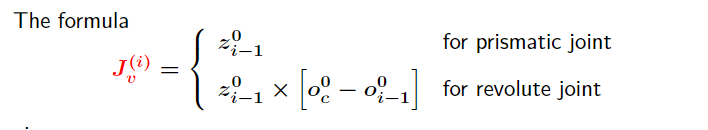

Zer = [0; 0; 0];
Jv1 = [cross(Z0,(Oc1-O0)), Zer]

$$Jv1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

Jv2 = [cross(Z0,(Oc2-O0)), Z1]

$$Jv2 = \left(\begin{array}{cc} -L\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ L\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

## Get the Angular velocity for each joint

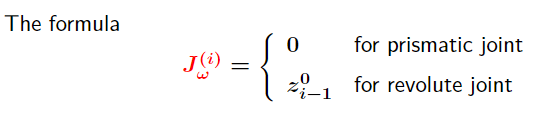

Jw1 = [Z0, Zer]

$$Jw1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Jw2 = [Z0 ,Zer]

$$Jw2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

## Get the rotation matrix for each joint

R1 = T01(1:3,1:3)

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = T02(1:3,1:3)

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

## Get the Kinetic energy

q = [q1;q2];
D1 = (m1*Jv1')*Jv1 + Jw1'*R1*I1*R1'*Jw1;
D2 = (m2*Jv2')*Jv2 + Jw2'*R2*I2*R2'*Jw2;

D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,L^{2}+2\,m_{2}\,L\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

## Get the Potential energy

P1 = 0;
P2 = m2*g*(L+q2)*sin(q1);
P = P1+P2;
G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(L+q_{2}\right)$$

G2 = diff(P, q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$


G = [G1; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(L+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

## Calculating Corilos and Centripetal forces

dq = [dq1; dq2];
ddq = [ddq1; ddq2];

C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(L+q_{2}\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(L+q_{2}\right)\\ -{\mathrm{dq}}_{1}\,m_{2}\,\left(L+q_{2}\right) & 0 \end{array}\right)$$

## Get the full Equation of Motion

tor = D*ddq+C*dq+G

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,L^{2}+2\,m_{2}\,L\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(L+q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(L+q_{2}\right)\\ -m_{2}\,\left(L+q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

tor_sub = subs(tor,{m1, m2, I1, I2, L, g},{2 2 2 1 0.2 9.81})

$$tor\_sub = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{1}{5}\right)}{50}+{\mathrm{ddq}}_{1}\,\left(2\,{q_{2}}^{2}+\frac{4\,q_{2}}{5}+\frac{77}{25}\right)+4\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(q_{2}+\frac{1}{5}\right)\\ 2\,{\mathrm{ddq}}_{2}+\frac{981\,\sin\left(q_{1}\right)}{50}-2\,{{\mathrm{dq}}_{1}}^{2}\,\left(q_{2}+\frac{1}{5}\right) \end{array}\right)$$

D(q1,q2) = subs(D,{m1, m2, I1, I2, L},{2 2 2 1 0.2})

$$D(q1, q2) = \left(\begin{array}{cc} 2\,{q_{2}}^{2}+\frac{4\,q_{2}}{5}+\frac{77}{25} & 0\\ 0 & 2 \end{array}\right)$$


C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2, L},{2 2 2 1 0.2})

$$C(q1, q2, dq1, dq2) = \left(\begin{array}{c} 4\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(q_{2}+\frac{1}{5}\right)\\ -2\,{{\mathrm{dq}}_{1}}^{2}\,\left(q_{2}+\frac{1}{5}\right) \end{array}\right)$$


G(q1,q2) = subs(G ,{m1, m2, I1, I2, L, g},{2 2 2 1 0.2 9.81})

$$G(q1, q2) = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{1}{5}\right)}{50}\\ \frac{981\,\sin\left(q_{1}\right)}{50} \end{array}\right)$$

## Plotting 1st test case

% Joint intial angles
q1_0 = 0;
q2_0 = 0;
% Joint intial velocities
dq1_0 = 0;
dq2_0 = 0;
% controller frequency
dt=0.01;
% Joint Torque and force
U = [15;5];
% No of points
n=600;
%Initialize the pos, vel and acceleration vectors
q1p=zeros(1,n);
q2p=zeros(1,n);

dq1p=zeros(1,n);
dq2p = zeros(1,n);

ddq1p=zeros(1,n);
ddq2p = zeros(1,n);

% Begin the loop
for i = 1:n
 % Put the initial pos and velocity in the pos and velocity vectors
 q1p(i)=q1_0;
 q2p(i)=q2_0;
 
 dq1p(i)=dq1_0;
 dq2p(i)=dq2_0;
 
 % Calculate the acceleration from the initial condition
 % inv(A) * b = A\b
 ddq = (D(q1_0, q2_0))\(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
 
 ddq1p(i) = ddq(1);
 ddq2p(i) = ddq(2);
 
 % Integrate the acc once to get the velocity
 dq1_0=dq1p(i) + double(ddq(1)*dt);
 dq2_0=dq2p(i) + double(ddq(2)*dt);

 %Integrate the velocity to get the position
 q1_0 = q1p(i) + dq1_0*dt;
 q2_0 = q2p(i) + dq2_0*dt;

end
t = 0:0.1:(0.1*(n-1));

## Plot the position

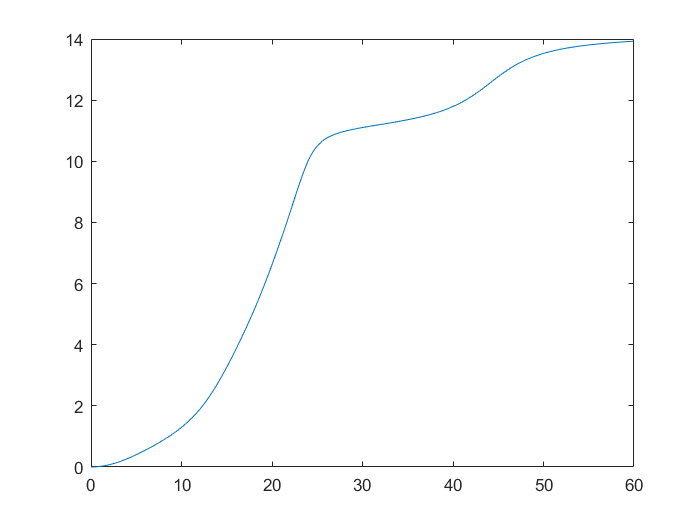

plot(t,q1p)

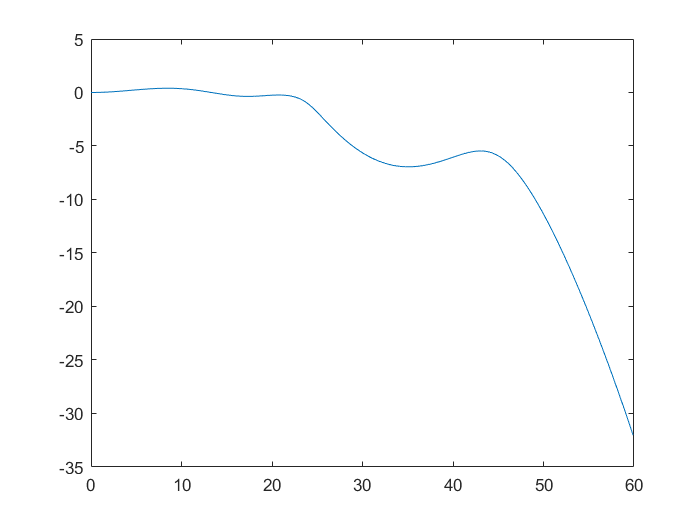

figure
plot(t,q2p)

## plot the Velocity

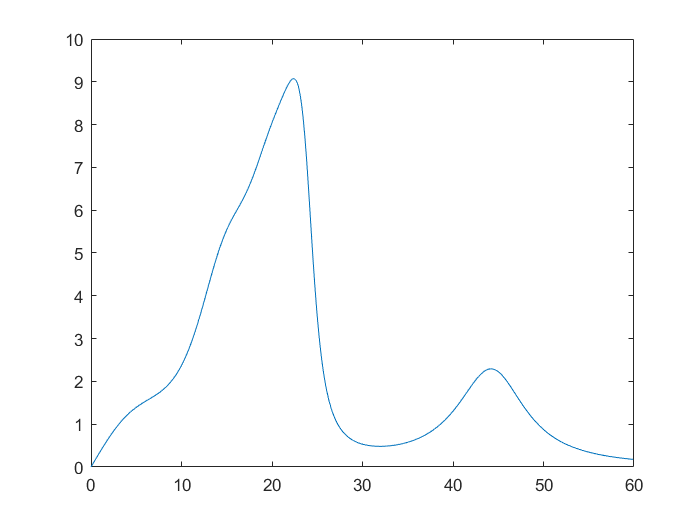

plot(t,dq1p)

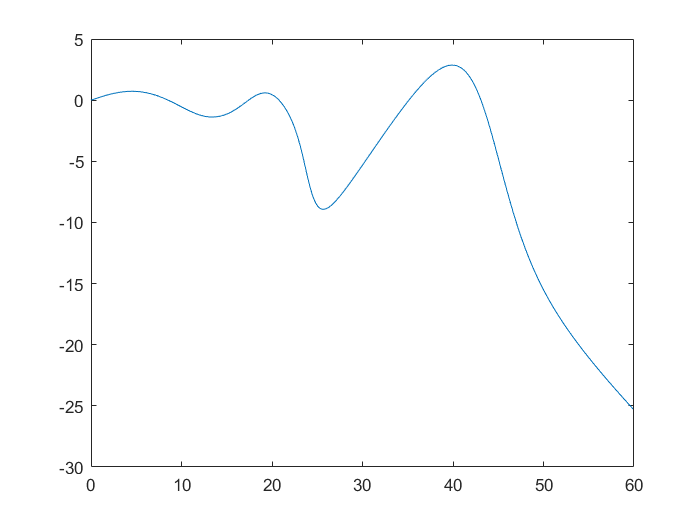

figure
plot(t,dq2p)

## plot the Acceleration

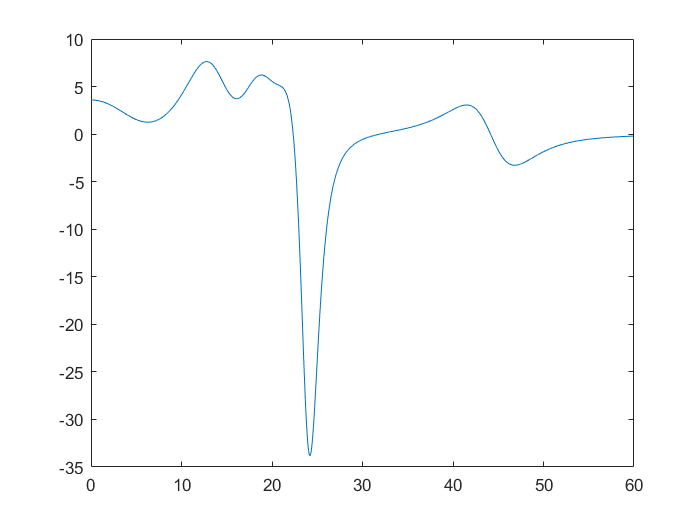

plot(t,ddq1p)

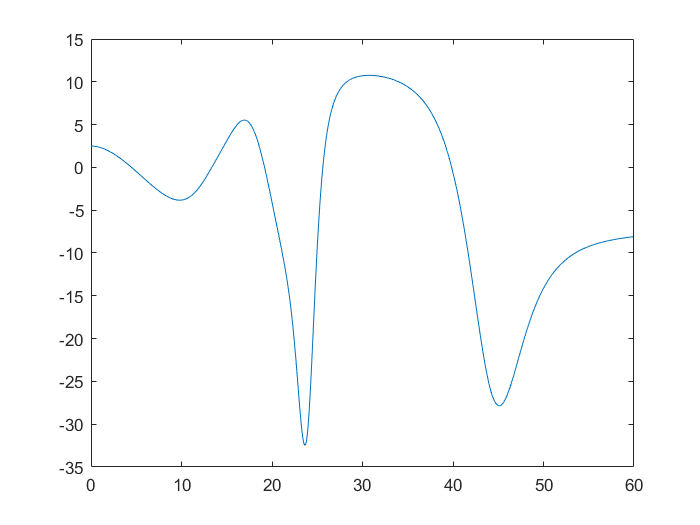

figure
plot(t,ddq2p)

## Plotting 2nd test case

% Joint intial angles
q1_0 = 0;
q2_0 = 0;
% Joint intial velocities
dq1_0 = 0;
dq2_0 = 0;
% No of points
n=500;
% controller frequency
dt=0.01;
% Joint Torque and force
U = zeros(n,2);

%Initialize the pos, vel and acceleration vectors
q1p=zeros(1,n);
q2p=zeros(1,n);

dq1p=zeros(1,n);
dq2p = zeros(1,n);

ddq1p=zeros(1,n);
ddq2p = zeros(1,n);
f = 1;
w = 2*pi*f;
t = 0:0.01:(0.01*(n-1));
U(:,2) = 10*sin(2*w*t);
U(:,1) = 25*cos(w*t);
% Begin the loop
for i = 1:n
 % Put the initial pos and velocity in the pos and velocity vectors
 q1p(i)=q1_0;
 q2p(i)=q2_0;
 
 dq1p(i)=dq1_0;
 dq2p(i)=dq2_0;
 

 % Calculate the acceleration from the initial condition
 % inv(A) * b = A\b
 ddq = (D(q1_0, q2_0))\(U(i,:)-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
 
 ddq1p(i) = ddq(1);
 ddq2p(i) = ddq(2);

 % Integrate the acc once to get the velocity
 dq1_0=dq1p(i) + double(ddq(1)*dt);
 dq2_0=dq2p(i) + double(ddq(2)*dt);

 %Integrate the velocity to get the position
 q1_0 = q1p(i) + dq1_0*dt;
 q2_0 = q2p(i) + dq2_0*dt;

end

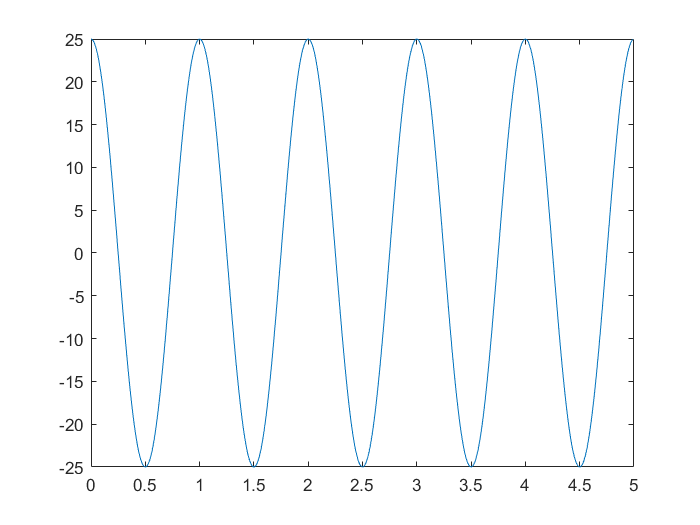

plot(t,U(:,1))

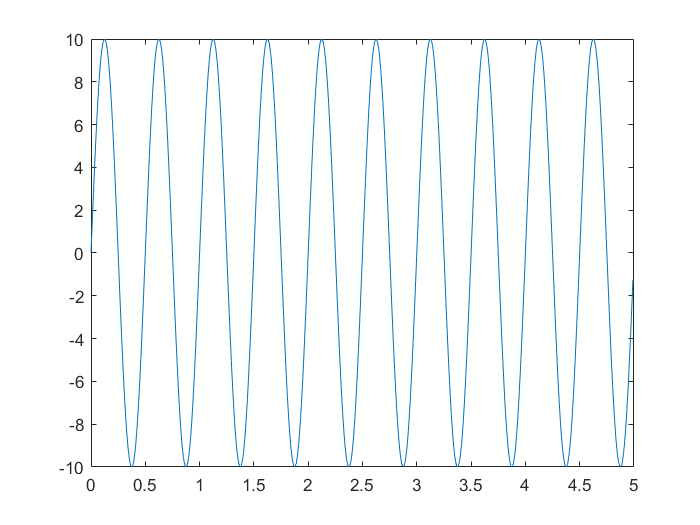

figure
plot(t,U(:,2))

## Plot the position

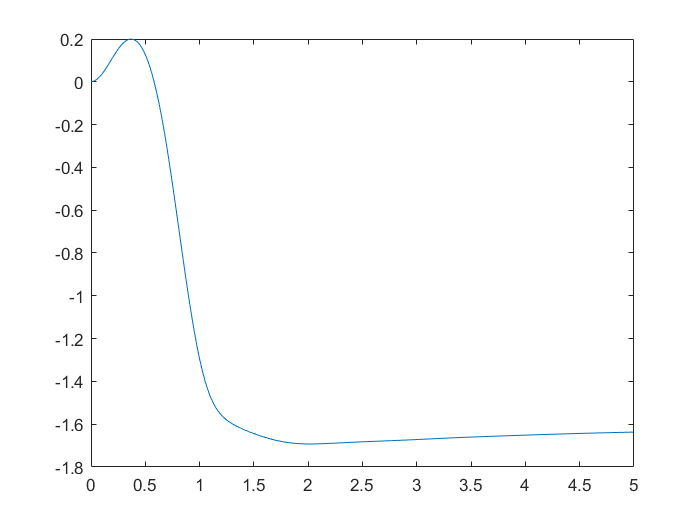

plot(t,q1p)

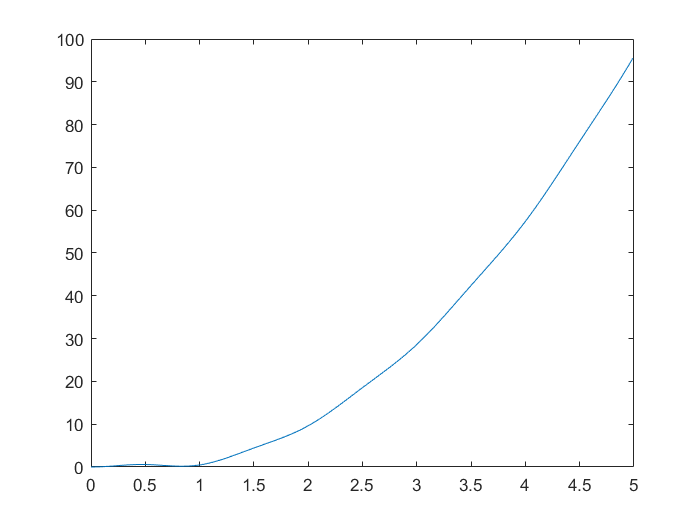

figure
plot(t,q2p)

## plot the Velocity

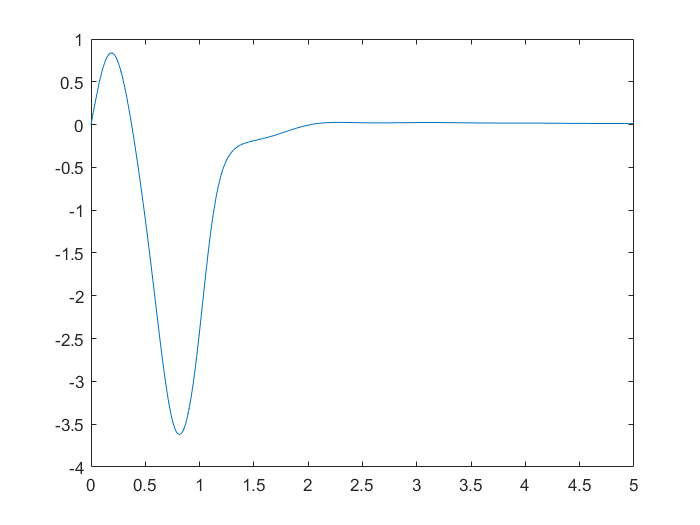

plot(t,dq1p)

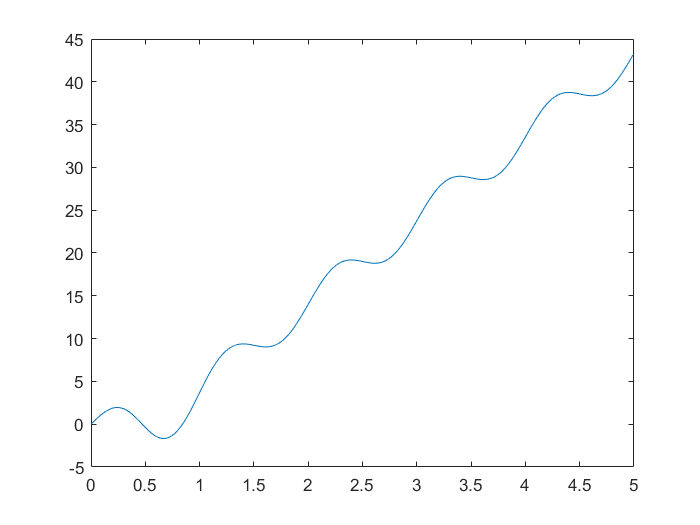

figure
plot(t,dq2p)

## plot the Acceleration

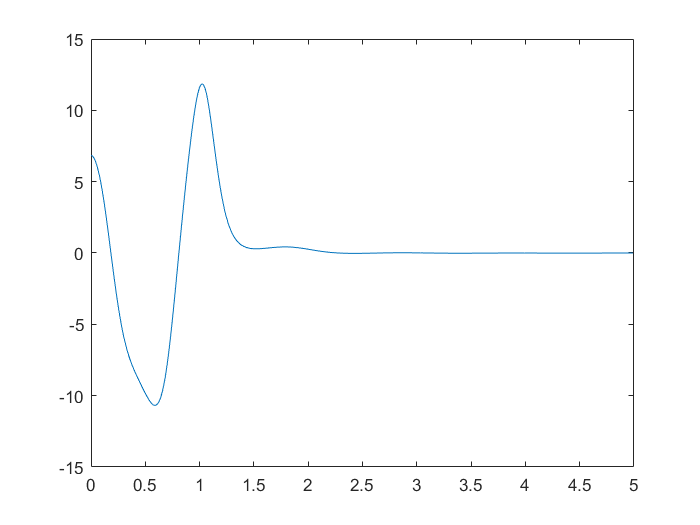

plot(t,ddq1p)

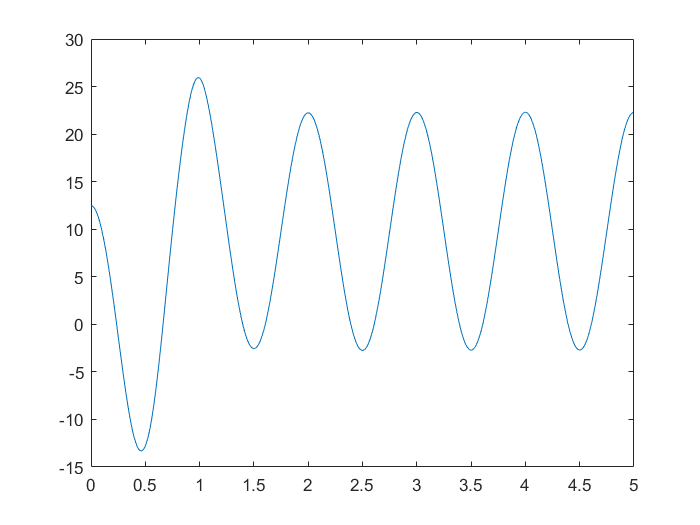

figure
plot(t,ddq2p)

## Plotting 3rd test case

% Joint intial angles
q1_0 = pi/2;
q2_0 = 0;
% Joint intial velocities
dq1_0 = 0;
dq2_0 = 0;
% controller frequency
dt=0.01;
% Joint Torque and force
U = [0;0];
% No of points
n=100;
%Initialize the pos, vel and acceleration vectors
q1p=zeros(1,n);
q2p=zeros(1,n);

dq1p=zeros(1,n);
dq2p = zeros(1,n);

ddq1p=zeros(1,n);
ddq2p = zeros(1,n);

% Begin the loop
for i = 1:n
 % Put the initial pos and velocity in the pos and velocity vectors
 q1p(i)=q1_0;
 q2p(i)=q2_0;
 
 dq1p(i)=dq1_0;
 dq2p(i)=dq2_0;
 
 % Calculate the acceleration from the initial condition
 % inv(A) * b = A\b
 ddq = (D(q1_0, q2_0))\(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
 
 ddq1p(i) = ddq(1);
 ddq2p(i) = ddq(2);
 
 % Integrate the acc once to get the velocity
 dq1_0=dq1p(i) + double(ddq(1)*dt);
 dq2_0=dq2p(i) + double(ddq(2)*dt);

 %Integrate the velocity to get the position
 q1_0 = q1p(i) + dq1_0*dt;
 q2_0 = q2p(i) + dq2_0*dt;

end
t = 0:0.1:(0.1*(n-1));

## Plot the position

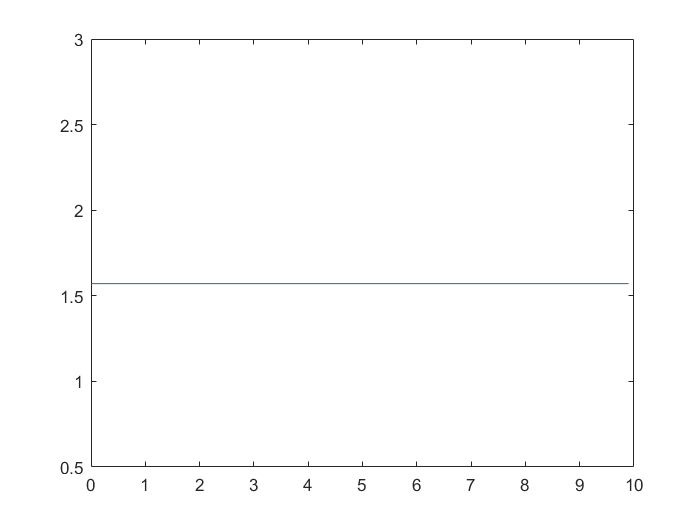

plot(t,q1p)

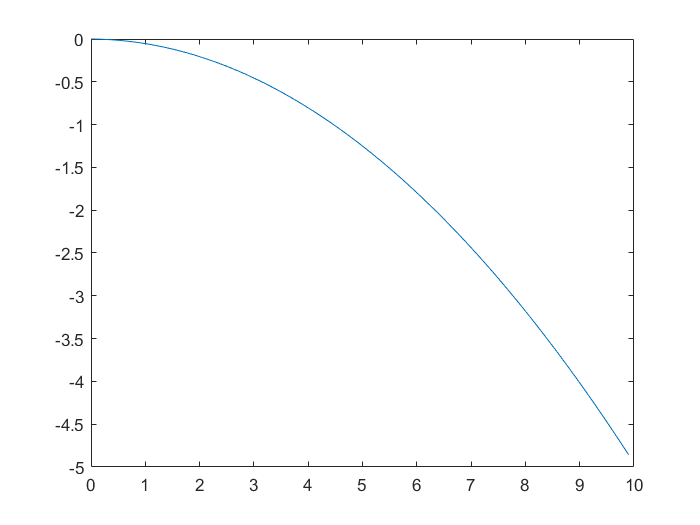

figure
plot(t,q2p)

## plot the Velocity

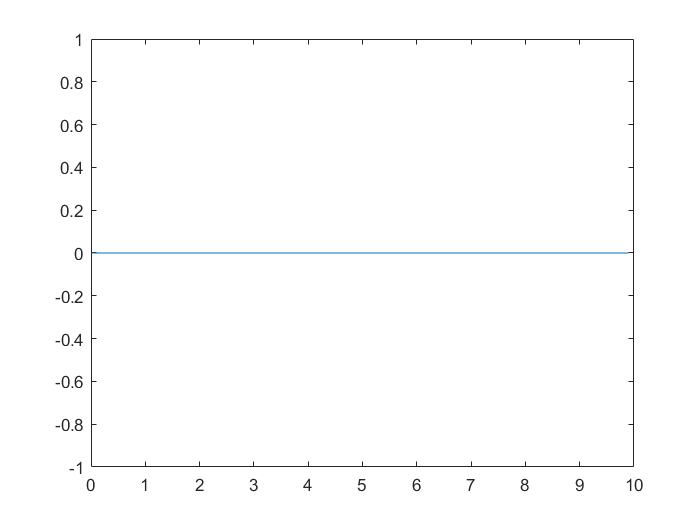

plot(t,dq1p)

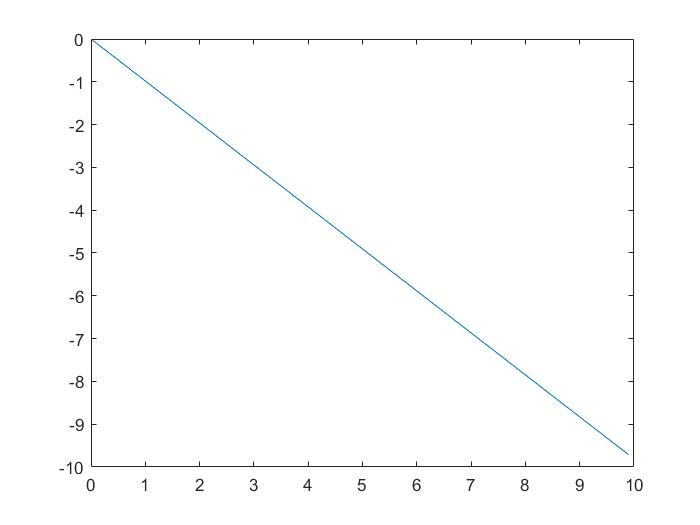

figure
plot(t,dq2p)

## plot the Acceleration

plot(t,ddq1p)

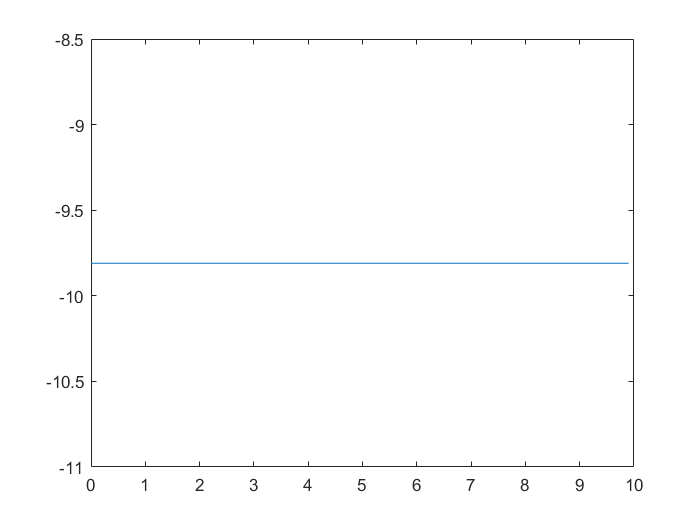

figure
plot(t,ddq2p)